%% Wczytanie zdjęcia w rozmiarze 768x480
zdj = 'zdj_3.bmp'

zdj = 'zdj_3.bmp'

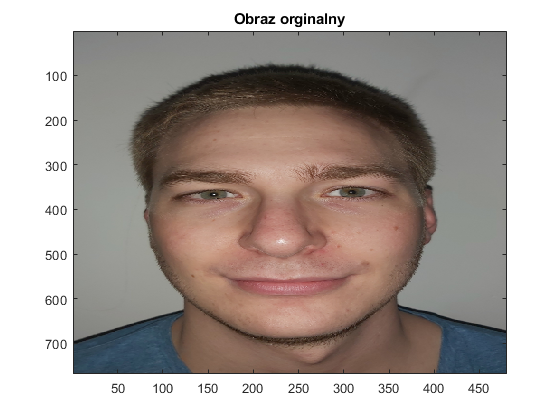

i = imread(zdj);
info = imfinfo(zdj);
j = 1;
figure(j);
imagesc(i); title('Obraz orginalny');

faceDetector = vision.CascadeObjectDetector;
bbox = faceDetector(i);
i_f = insertObjectAnnotation(i, 'rectangle', bbox, 'Face');

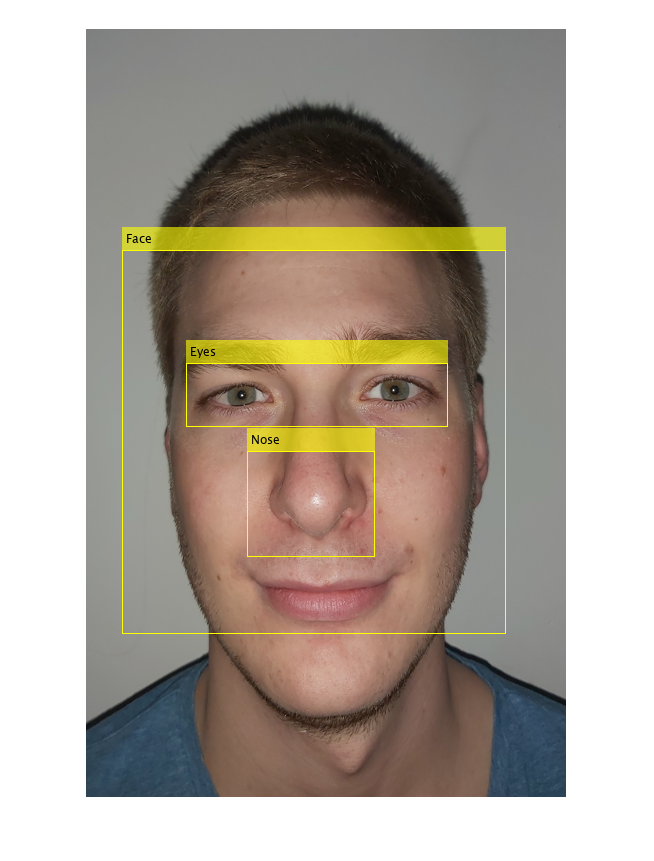

bothEyes = vision.CascadeObjectDetector('ClassificationModel','EyePairBig');
bothEyes.MergeThreshold = 10; bothEyes.MinSize = [30 200];
nose = vision.CascadeObjectDetector('ClassificationModel','Nose', 'UseROI', true);
nose.MergeThreshold = 20; nose.MinSize = [70 40];


bothEyesbbox = bothEyes(i);
i_f = insertObjectAnnotation(i_f, 'rectangle', bothEyesbbox, 'Eyes');
nosebbox = nose(i, bbox);
i_f = insertObjectAnnotation(i_f, 'rectangle', nosebbox, 'Nose');
imshow(i_f); 

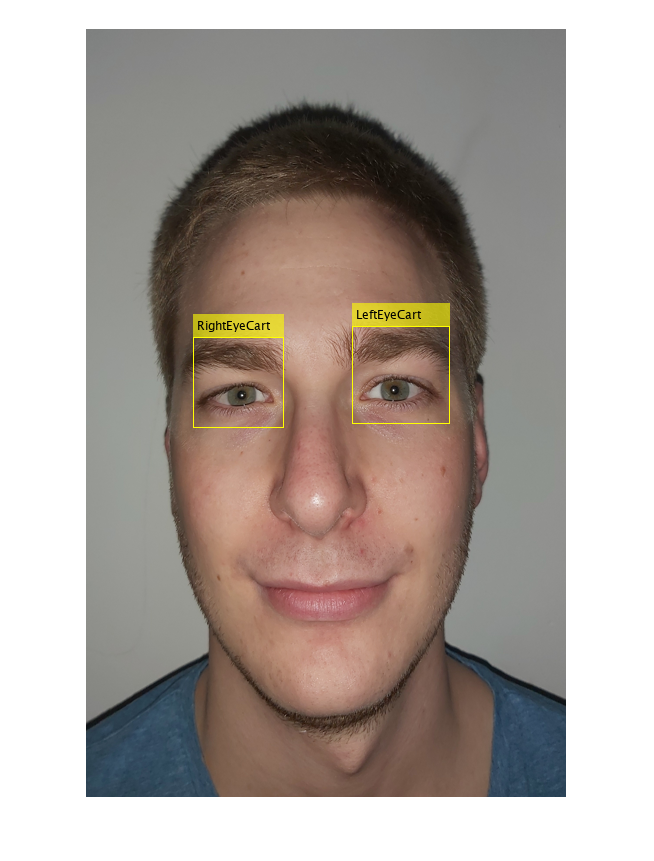

% Klasyfikacja wstępna
lEyeCart = vision.CascadeObjectDetector('ClassificationModel','LeftEyeCART');
lEyeCart.MergeThreshold = 15; lEyeCart.MinSize = [30 60];
rEyeCart = vision.CascadeObjectDetector('ClassificationModel','RightEyeCART');
rEyeCart.MergeThreshold = 15; rEyeCart.MinSize = [30 60];

lEyeCartbbox = lEyeCart(i);
i_e = insertObjectAnnotation(i, 'rectangle', lEyeCartbbox, 'LeftEyeCart');
rEyeCartbbox = rEyeCart(i);
i_e = insertObjectAnnotation(i_e, 'rectangle', rEyeCartbbox, 'RightEyeCart');
imshow(i_e);

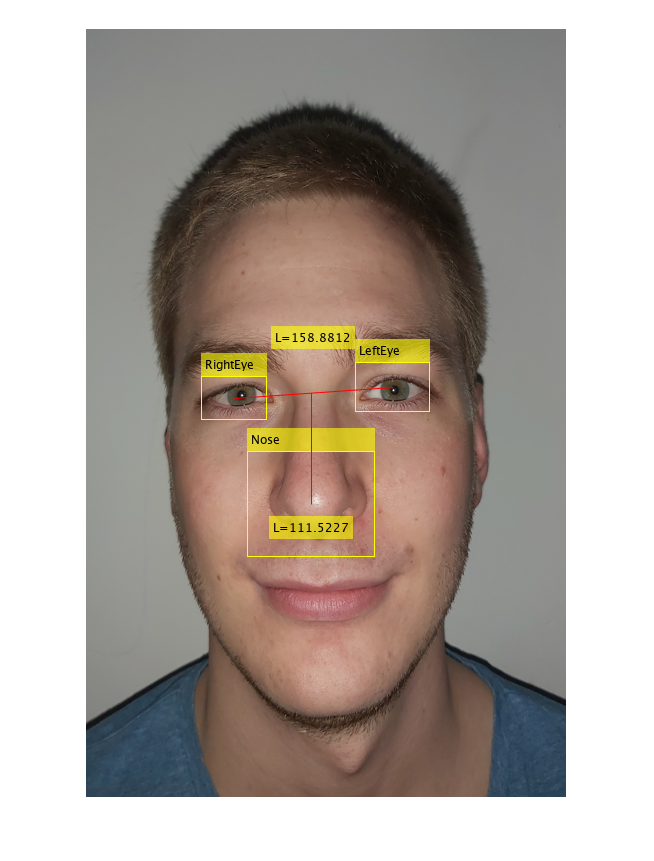


% klasyfikacja dokladna, mniejszy klasyfikator, dodany region of intrest i
% merge aby nie bylo kilka detekcji
lEye = vision.CascadeObjectDetector('ClassificationModel','LeftEye', 'UseROI', true);
lEye.MergeThreshold = 10;
rEye = vision.CascadeObjectDetector('ClassificationModel','RightEye', 'UseROI', true);
rEye.MergeThreshold = 10;

lEyebbox = lEye(i, lEyeCartbbox);
i_e2 = insertObjectAnnotation(i, 'rectangle', lEyebbox, 'LeftEye');
rEyebbox = rEye(i, rEyeCartbbox);
i_e2 = insertObjectAnnotation(i_e2, 'rectangle', rEyebbox, 'RightEye');
i_e2 = insertObjectAnnotation(i_e2, 'rectangle', nosebbox, 'Nose');

% nos
xn = nosebbox(1) + nosebbox(3)/2; yn=nosebbox(2)+nosebbox(4)/2;

% srodki oczu
xl = lEyebbox(1) + lEyebbox(3)/2; yl = lEyebbox(2) + lEyebbox(4)/2;
xr = rEyebbox(1) + rEyebbox(3)/2; yr = rEyebbox(2) + rEyebbox(4)/2;
ys = (yr+yl)/2; xs = (xr+xl)/2;
L = sqrt((xl-xr)^2+(yl-yr)^2);
L2 = sqrt((xs-xn)^2+(ys-yn)^2);

i_e2 = insertText(i_e2, [xs, ys*0.85], ['L=' num2str(L)], 'AnchorPoint',"Center");
i_e2 = insertText(i_e2, [xn, yn*1.05], ['L=' num2str(L2)], 'AnchorPoint',"Center");
imshow(i_e2); hold on;
line([xr, xl], [yr, yl], 'Color','red');
line([xn xn], [yn ys], 'Color','red'); hold off;